# **demo10 of Im2mesh package**

demo10 - Different polyline smoothing technique

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

## Shape

Let's start demo. Import image Shape.tif.

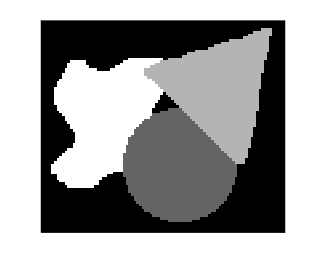

im = imread('Shape.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

## Extract boundaries & find control points

We use function getCtrlPnts to find and label control points.

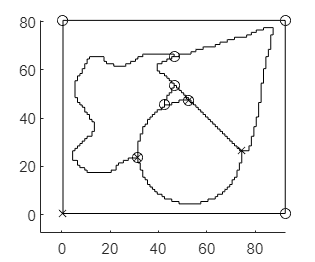

% image to polygon boundary
boundsRaw = im2Bounds( im );

% label control points
tf_avoid_sharp_corner = false;
boundsCtrlP = getCtrlPnts( boundsRaw, tf_avoid_sharp_corner, size(im) );

plotBounds(boundsCtrlP, true);     % show starting and control points

## Smooth boundary using Taubin method

We use function smoothBounds to smooth boundary. Inside function smoothBounds, it's the Taubin smoothing method ([https://doi.org/10.1109/ICCV.1995.466848](https://doi.org/10.1109/ICCV.1995.466848)).

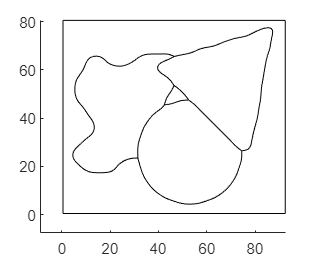

lambda = 0.5;
mu = -0.5;
iters = 100;
threshold_num_turning = 4;
threshold_num_vert_Smo = 4;

boundsTaubin = smoothBounds( boundsCtrlP, lambda, mu, iters, ...
                threshold_num_turning, threshold_num_vert_Smo );

plotBounds(boundsTaubin);

## Smooth boundary using CCMA method

Let's try another smoothing method - Curvature Corrected Moving Average (CCMA) method ([https://github.com/UniBwTAS/ccma](https://github.com/UniBwTAS/ccma)). Because Im2mesh package has a good and clear workflow, we can easily implement CCMA method via "smoothBoundsCCMA.m". Function smoothBoundsCCMA is just slightly different from function smoothBounds.

Here is some info about the input of function smoothBoundsCCMA.

Let's try it.

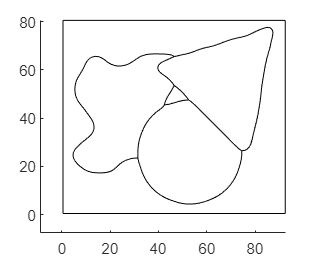

w_ma = 30;
w_cc = 3;
threshold_num_turning = 4;
threshold_num_vert_Smo = 4;

boundsCCMA = smoothBoundsCCMA( boundsCtrlP, w_ma, w_cc, ...
                threshold_num_turning, threshold_num_vert_Smo );

plotBounds(boundsCCMA);

## Plot together

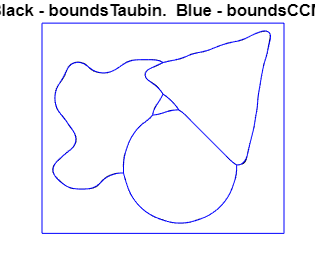

plotBounds2( boundsTaubin, boundsCCMA );

## Zoom in

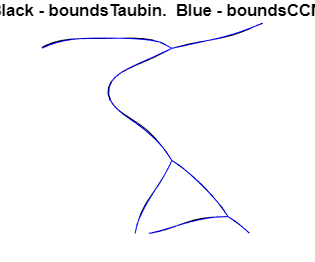

plotBounds2( boundsTaubin, boundsCCMA );

xlim([32.6 58.5])
ylim([45.7 68.2])

Very good! It seems the result of CCMA method is quite similar to that of Taubin method for our data.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo